%矩阵输入
a=[1 2 3;
    4 5 6;
    7 8 9]%矩阵输入

a =      1     2     3
     4     5     6
     7     8     9


A=[[a;[1 2 3]],[1;2;3;4]]%矩阵维数变换

A =      1     2     3     1
     4     5     6     2
     7     8     9     3
     1     2     3     4


B=[1+9i 2+8i 3+7i;4+6i 5+5i 6+4i ;7+3i 8+2i 9+1i]%虚数阵

B =    1.0000 + 9.0000i   2.0000 + 8.0000i   3.0000 + 7.0000i
   4.0000 + 6.0000i   5.0000 + 5.0000i   6.0000 + 4.0000i
   7.0000 + 3.0000i   8.0000 + 2.0000i   9.0000 + 1.0000i


%冒号的用法
v1=0:.2:pi  %从0开始步长为0.2截取数据

v1 =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000


v2=0:-.2:pi %从0开始步长-0.2到pi截取数据


v2 =

  空的 1×0 double 行向量



v3=pi:-.2:0 %从pi到0步长-0.2截取数据

v3 =     3.1416    2.9416    2.7416    2.5416    2.3416    2.1416    1.9416    1.7416    1.5416    1.3416    1.1416    0.9416    0.7416    0.5416    0.3416    0.1416


B1=a(1:2:end,:)

B1 =      1     2     3
     7     8     9


B2=a([3,2,1],[1,1,1])

B2 =      7     7     7
     4     4     4
     1     1     1


B3=a(:,end:-1:1)

B3 =      3     2     1
     6     5     4
     9     8     7


%数学运算
T1=B'%共轭转置

T1 =    1.0000 - 9.0000i   4.0000 - 6.0000i   7.0000 - 3.0000i
   2.0000 - 8.0000i   5.0000 - 5.0000i   8.0000 - 2.0000i
   3.0000 - 7.0000i   6.0000 - 4.0000i   9.0000 - 1.0000i


T2=B.'%转置

T2 =    1.0000 + 9.0000i   4.0000 + 6.0000i   7.0000 + 3.0000i
   2.0000 + 8.0000i   5.0000 + 5.0000i   8.0000 + 2.0000i
   3.0000 + 7.0000i   6.0000 + 4.0000i   9.0000 + 1.0000i


b=B-a

b =    0.0000 + 9.0000i   0.0000 + 8.0000i   0.0000 + 7.0000i
   0.0000 + 6.0000i   0.0000 + 5.0000i   0.0000 + 4.0000i
   0.0000 + 3.0000i   0.0000 + 2.0000i   0.0000 + 1.0000i


E=eye(3)

E =      1     0     0
     0     1     0
     0     0     1


C=a*E

C =      1     2     3
     4     5     6
     7     8     9


fA=fliplr(A)

fA =      1     3     2     1
     2     6     5     4
     3     9     8     7
     4     3     2     1


fB=flipud(B)

fB =    7.0000 + 3.0000i   8.0000 + 2.0000i   9.0000 + 1.0000i
   4.0000 + 6.0000i   5.0000 + 5.0000i   6.0000 + 4.0000i
   1.0000 + 9.0000i   2.0000 + 8.0000i   3.0000 + 7.0000i


D=rot90(a)

D =      3     6     9
     2     5     8
     1     4     7


aa=a.^a

aa =            1           4          27
         256        3125       46656
      823543    16777216   387420489


%矩阵逻辑运算
Al=[1:3;0 0 0;4:6]

Al =      1     2     3
     0     0     0
     4     5     6


Bl=[0 0 0;1 1 1;3 5 7]

Bl =      0     0     0
     1     1     1
     3     5     7


Cl1=Al&Bl

Cl1 = 3×3 logical 数组
   0   0   0
   0   0   0
   1   1   1


Cl2=Al|Bl

Cl2 = 3×3 logical 数组
   1   1   1
   1   1   1
   1   1   1


Cl3=xor(Al,Bl)

Cl3 = 3×3 logical 数组
   1   1   1
   1   1   1
   0   0   0


Cl4=~Al

Cl4 = 3×3 logical 数组
   0   0   0
   1   1   1
   0   0   0


%矩阵比较运算
find(a>=5)%按照列向量的查找

ans =      3
     5
     6
     8
     9


all(a(:)>=5)%全部大于等于5则为1反之为0

ans = logical
   0


any(a(:)>=5)%只要存在大于等于5的就为1

ans = logical
   1


%化简与变换
syms s;
p=(s+3)^2*(s^2+3*s+2)*(s^3+12*s^2+48*s+64)

$$p = {\left(s+3\right)}^{2}\,\left(s^{2}+3\,s+2\right)\,\left(s^{3}+12\,s^{2}+48\,s+64\right)$$

P1=simplify(p)

$$P1 = {\left(s+3\right)}^{2}\,{\left(s+4\right)}^{3}\,\left(s^{2}+3\,s+2\right)$$

P2=expand(p)

$$P2 = s^{7}+21\,s^{6}+185\,s^{5}+883\,s^{4}+2454\,s^{3}+3944\,s^{2}+3360\,s+1152$$

syms z
P3=simplify(subs(P2,s,(z-1)/(z+1)))

$$P3 = \frac{8\,z\,{\left(2\,z+1\right)}^{2}\,\left(3\,z+1\right)\,{\left(5\,z+3\right)}^{3}}{{\left(z+1\right)}^{7}}$$

latex(P3)

ans = '\frac{8\,z\,{\left(2\,z+1\right)}^2\,\left(3\,z+1\right)\,{\left(5\,z+3\right)}^3}{{\left(z+1\right)}^7}'

%数论计算
AA=[-.2756,0.569,1.4597,2.356,1.946,-1.655]

AA =    -0.2756    0.5690    1.4597    2.3560    1.9460   -1.6550


V1=floor(AA)%负无穷方向

V1 =     -1     0     1     2     1    -2


V2=ceil(AA)%正无穷方向

V2 =      0     1     2     3     2    -1


V3=round(AA)%最近的整数

V3 =      0     1     1     2     2    -2


V4=fix(AA)%近零方向

V4 =      0     0     1     2     1    -1


Ah=hilb(3)

Ah =     1.0000    0.5000    0.3333
    0.5000    0.3333    0.2500
    0.3333    0.2500    0.2000


[~,d]=rat(Ah)

d =      1     2     3
     2     3     4
     3     4     5


m=sym(125800)

$$m = 125800$$

n=sym(365894)

$$n = 365894$$

gcd(m,n)

$$ans = 2$$

lcm(m,n)

$$ans = 23014732600$$

factor(lcm(m,n))

$$ans = \left(\begin{array}{ccccccccc} 2 & 2 & 2 & 5 & 5 & 17 & 37 & 113 & 1619 \end{array}\right)$$

lcm(lcm(3,5),7)

ans = 105

AZS=1:10000

AZS =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


BZS=AZS(isprime(AZS))%isprime返回的是下标

BZS =      2     3     5     7    11    13    17    19    23    29    31    37    41    43    47    53    59    61    67    71    73    79    83    89    97   101   103   107   109   113   127   131   137   139   149   151   157   163   167   173   179   181   191   193   197   199   211   223   227   229



%Matlab流程结构%
%循环
s1=0;
for k=1:100
    s1=s1+k;
end,s1

s1 = 5050

s2=0;
n=1;
while(n<=100)
    s2=s2+n;
    n=n+1;
end,s2

s2 = 5050


s=0;
for kk=1:10000
    s=s+kk;
    if(s>10000)
        break;
    end
end,s

s = 10011


for count=1:10
    switch count
        case 1,count
        case 2,i=count
        otherwise
    end
end

count = 1

i = 2

%异常捕捉
syms s;
p=(s+3)^2*(s^2+3*s+2)*(s^3+12*s^2+48*s+64);
try
    P12=simple(p)
catch
    P22=simplify(p)
end

$$P22 = {\left(s+3\right)}^{2}\,{\left(s+4\right)}^{3}\,\left(s^{2}+3\,s+2\right)$$

%隐式定义函数
f=@(x)sin(x)

f = 包含以下值的 function_handle :
    @(x)sin(x)


for x=0:pi/6:pi
    f(x)
end

ans = 0

ans = 0.5000

ans = 0.8660

ans = 1

ans = 0.8660

ans = 0.5000

ans = 1.2246e-16

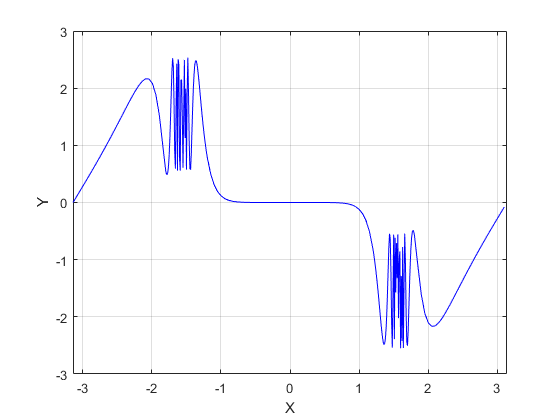

%伪代码
pcode findsum.m -inplace

%二维绘图
x1=[-pi:0.05:-1.8,-1.799:0.01:-1.2,-1.199:0.05:1.2,1.201:0.01:1.8,1.801:0.05:pi];
y1=sin(tan(x1))-tan(sin(x1));
plot(x1,y1,'b')
xlim([-pi pi])
xlabel('X')
ylabel('Y')
grid on

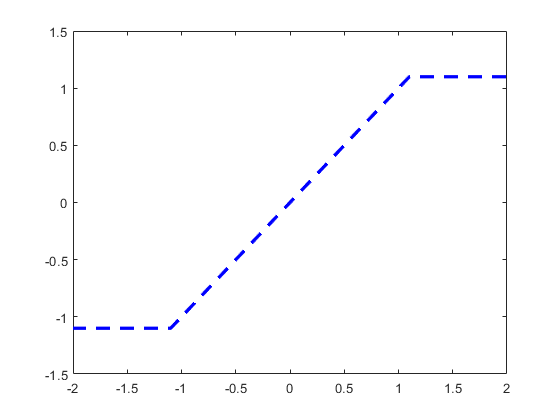


x2=-2:0.02:2;
y2=1.1*sign(x2).*(abs(x2)>1.1)+x2.*(abs(x2)<=1.1);
plot(x2,y2,'Color','b','LineStyle','--','LineWidth',2.5);

hold off

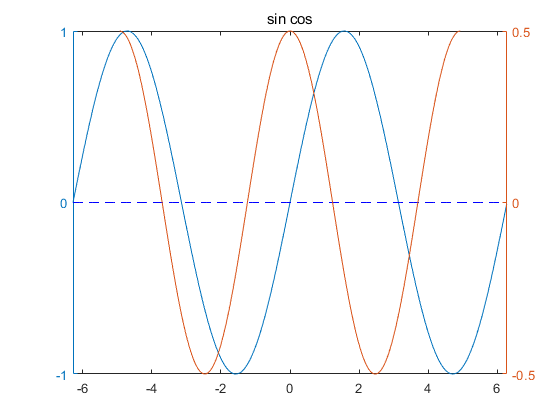

x=-2*pi:0.01:2*pi;
y3=sin(x);
y4=0.5*cos(x);
y5=0*x;
plotyy(x,y3,x,y4);
hold on
plot(x,y5,'--','Color','b');
title('sin cos')
xlim([-2*pi 2*pi])
hold off

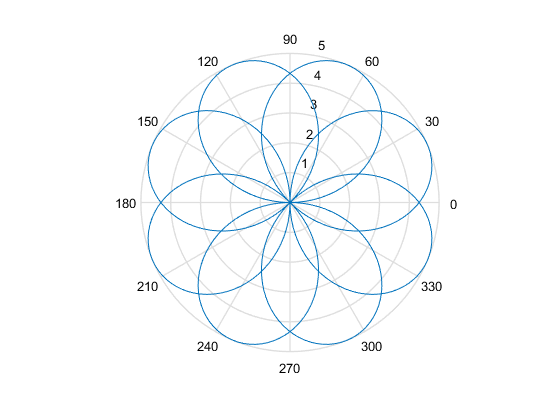

%极坐标
theta=0:0.04:6*pi;
rho=5*sin(4*theta/3);
polar(theta,rho);

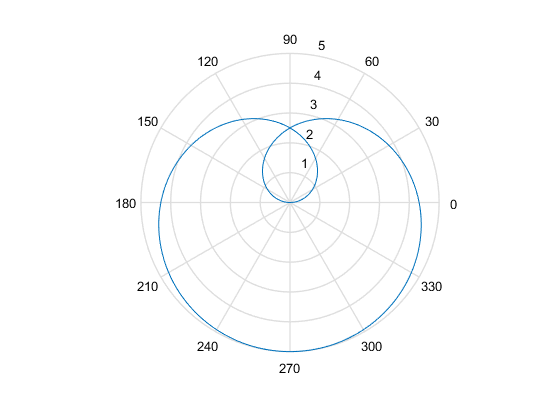

rho1=5*sin(theta/3);
polar(theta,rho1);

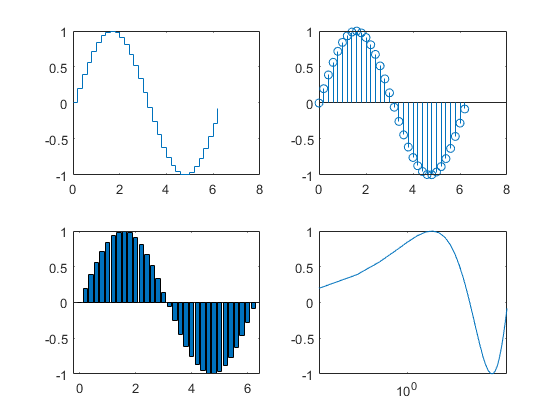

%其他图表
t=0:0.2:2*pi;
yt=sin(t);
subplot(2,2,1),stairs(t,yt);
subplot(2,2,2),stem(t,yt);
subplot(2,2,3),bar(t,yt);
subplot(2,2,4),semilogx(t,yt);

%隐式绘图
f=@(xz,yz)xz.^2.*sin(xz+yz.^2)+yz.^2.*exp(xz+yz)+5*cos(xz.^2+yz)

f = 包含以下值的 function_handle :
    @(xz,yz)xz.^2.*sin(xz+yz.^2)+yz.^2.*exp(xz+yz)+5*cos(xz.^2+yz)


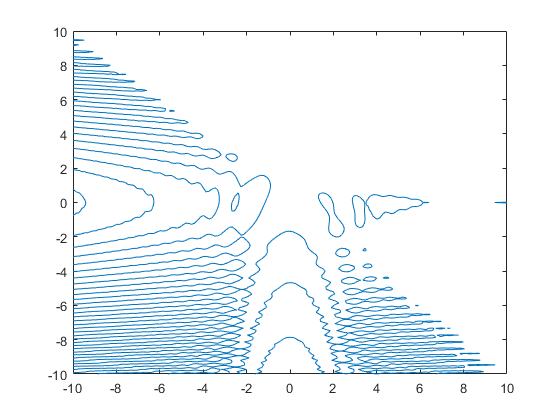

figure
fimplicit(f,[-10 10]);

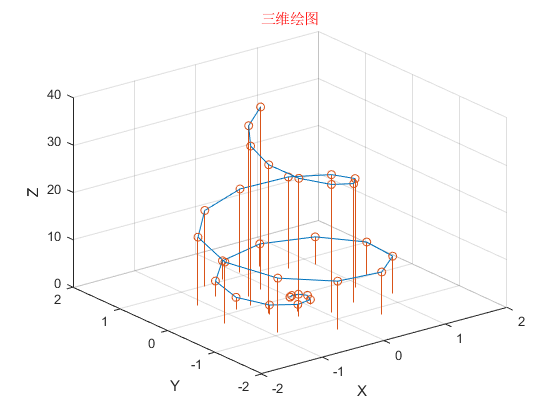


%三维绘图
figure;
tt=0:0.1:2*pi;
xt=t.^3.*exp(-t).*sin(3*t);
yt=t.^3.*exp(-t).*cos(3*t);
zt=t.^2;
plot3(xt,yt,zt);
hold on
stem3(xt,yt,zt);
hold off
grid
xlabel('X')
ylabel('Y')
zlabel('Z')
title("三维绘图",'Color','r')

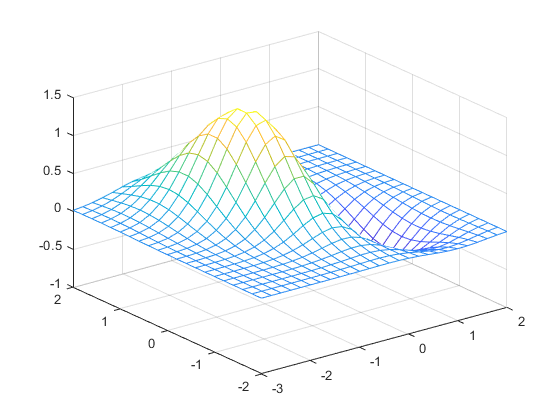


%三维曲面
[x,y]=meshgrid(-3:0.2:2,-2:.2:2);
z=(x.^2-2*x).*exp(-x.^2-y.^2-x.*y);
mesh(x,y,z);

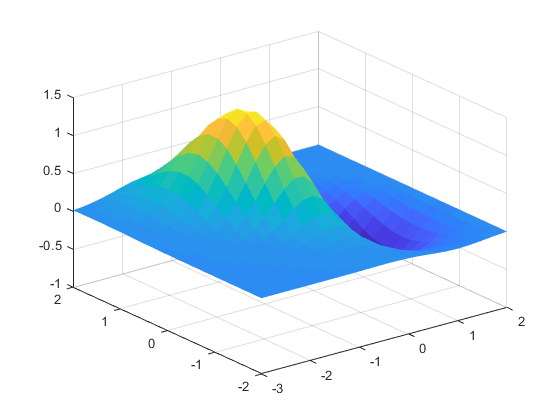

figure
surf(x,y,z),shading flat;

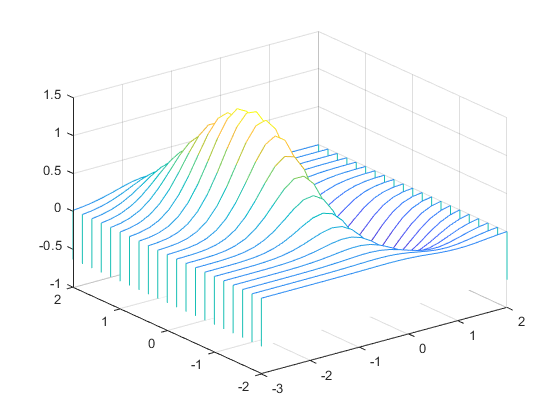

figure
waterfall(x,y,z)

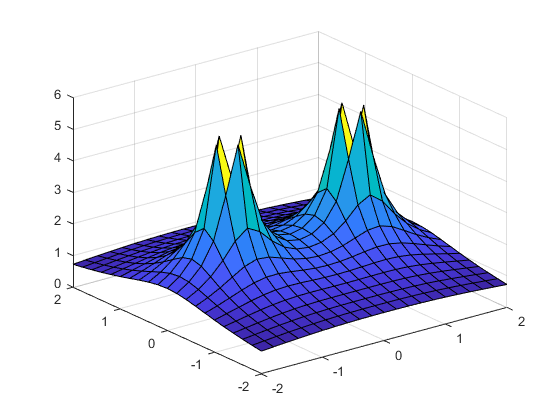

%例子
[x,y]=meshgrid(-2:0.2:2);
z=1./(sqrt((1-x).^2+y.^2))+1./(sqrt((1+x).^2+y.^2));
figure
surf(x,y,z);

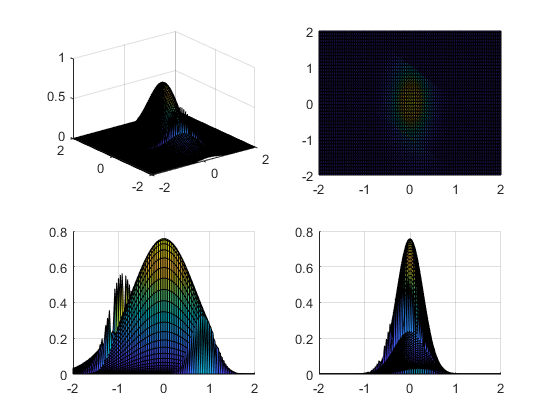


figure
[x,y]=meshgrid(-2:.04:2,-2:.04:2);
z=0.5457*exp(-0.7*y.^2-3.75.^2-x).*(x+y>1)+...
    0.7575*exp(-y.^2-6*x.^2).*((x+y>=-1)&(x+y<=1))+...
    0.5457*exp(-0.75*y.^2-3.75*x.^2+1.5*x).*(x+y<=-1);
%handle=surf(x,y,z);shading flat;
subplot(2,2,1),surf(x,y,z);
subplot(2,2,2),surf(x,y,z),view(0,90);
subplot(2,2,3),surf(x,y,z),view(90,0);
subplot(2,2,4),surf(x,y,z),view(0,0);

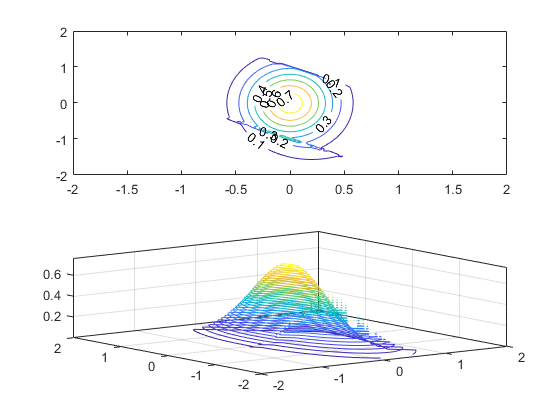


figure;
subplot(2,1,1),[c,h]=contour(x,y,z);clabel(c,h);
subplot(2,1,2),contour3(x,y,z,30);

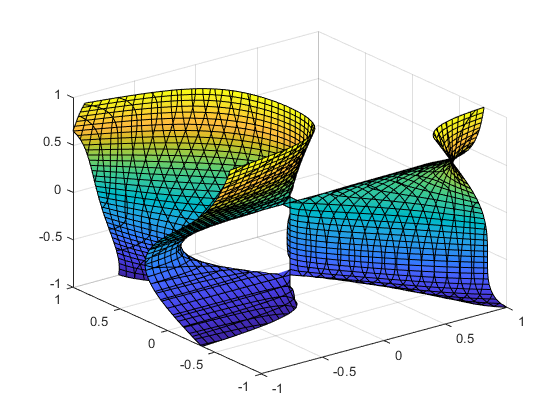


figure;
f=@(x,y,z)x.*sin(y+z.^2)+y.^2.*cos(x+z)+z.*x.*cos(z+y.^2);
fimplicit3(f,[-1,1]);

syms x n a;
% x=-100:0.01:100;
% f=sin(x)./x;
% plot(x,f,'r')
% grid

%极限
% syms x a b;
% f=x*(1+a/x)^x*sin(b/x);
% limit(f,x,inf)%极限

% syms x;
% f=(exp(x.^3)-1)./(1-cos(sqrt(x-sin(x))));
% limit(f,x,0,'right')
% fplot(f,[-0.1,0.1]);
% hold on 
% plot(0,12,'o')
% hold off
% xlim([-0.1,0.1])
% ylim([11.995,12.015])

% f=tan(x);
% limit(f,x,pi/2,'left')
% limit(f,x,pi/2,'right')

% f=(n^(2/3)*sin(factorial(n)))/(n+1)
% limit(f,n,inf)

% f=n*atan(1/(n*(x^2+1)+x))*tan(pi/4+x/2/n)^n
% limit(f,n,inf)
syms y ;
% f=exp(-1/(x^2+y^2))*sin(x)^2/x^2*(1+1/y^2)^(x+a^2*y^2)
% limit(limit(f,x,1/sqrt(y)),y,inf)

% f=((x*y)/(x^2+y^2))^(x^2)
% limit(limit(f,y,inf),x,inf)
% limit(limit(f,x,inf),y,inf)
% limit(limit(f,y,x^2),x,inf)
% limit(limit(f,x,y^2),y,inf)

%f=(sin(x))/(x^2+4*x+3)
% f1=diff(f)
% f4=diff(f,x,4),latex(f4)
% fplot(f,[0,5]),hold on ,fplot(f1,[0,5]);
% f4=collect(simplify(f4),sin(x))
% collect(simplify(f4),cos(x))

% syms t;y=str2sym('f(t)');
% g=simplify(diff(t^2*y*sin(t),t,3))
% y1=simplify(subs(g,y,exp(-t)))

% H=[4*sin(5*x) exp(-4*x^2);
%     3*x^2+4*x+1 sqrt(4*x^2+2)]
% H3=diff(H,x,3)

% y=sin(t)/(t+1)^3;
% x=cos(t)/(t+1)^3;
% simplify(paradiff(y,x,t,3))

% z=(x^2-2*x)*exp(-x^2-y^2-x*y);
% zx=simplify(diff(z,x),'Criterion','default');
% zy=simplify(diff(z,y),'Criterion','default');
% [x0,y0]=meshgrid(-3:0.2:2,-2:0.2:2);
% z0=subs(z,{x,y},{x0,y0});
% % h=surf(x0,y0,z0)
% contour(x0,y0,z0,30)
% hold on 
% zx0=subs(zx,{x,y},{x0,y0});
% zy0=subs(zy,{x,y},{x0,y0});
% quiver(x0,y0,-zx0,-zy0)

syms x y z;
% f=sin(x^2*y)*exp(-x^2*y-z^2)
% df=simplify(diff(diff(diff(f,x,2),y),z),'Criterion','default')
% f=(x^2-2*x)*exp(-x^2-y^2-x*y)
% F1=impldiff(f,x,y,1)
% F3=impldiff(f,x,y,3)
% f=x^2+x*y+y^2-3
% F1=impldiff(f,x,y,1)
% f2=impldiff(f,x,y,2);F2=subs(f2,x^2+x*y+y^2,3)
% f3=impldiff(f,x,y,3);F3=subs(f3,x^2+x*y+y^2,3)
% f4=impldiff(f,x,y,4);F4=subs(f4,x^2+x*y+y^2,3)
%jacobian 矩阵
% syms r theta phi;
% x=r*sin(theta)*cos(phi)
% y=r*sin(theta)*sin(phi)
% z=r*cos(theta)
% J=jacobian([x,y,z],[r theta phi])
%Hess矩阵
f=(x^2-2*x)*exp(-x^2-y^2-x*y);
simplify(hessian(f,[x,y]),'Criterion','default')

$$ans = \begin{array}{l} \left(\begin{array}{cc} \sigma_{2}\,\left(4\,x^{4}+4\,x^{3}\,y-8\,x^{3}+x^{2}\,y^{2}-8\,x^{2}\,y-10\,x^{2}-2\,x\,y^{2}-4\,x\,y+12\,x+4\,y+2\right) & \sigma_{1}\\ \sigma_{1} & x\,\sigma_{2}\,\left(x-2\right)\,\left(x^{2}+4\,x\,y+4\,y^{2}-2\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{2}\,\left(2\,x^{4}+5\,x^{3}\,y-4\,x^{3}+2\,x^{2}\,y^{2}-10\,x^{2}\,y-3\,x^{2}-4\,x\,y^{2}-4\,x\,y+4\,x+4\,y\right)\\ \sigma_{2}={\mathrm{e}}^{-x^{2}-x\,y-y^{2}} \end{array}$$